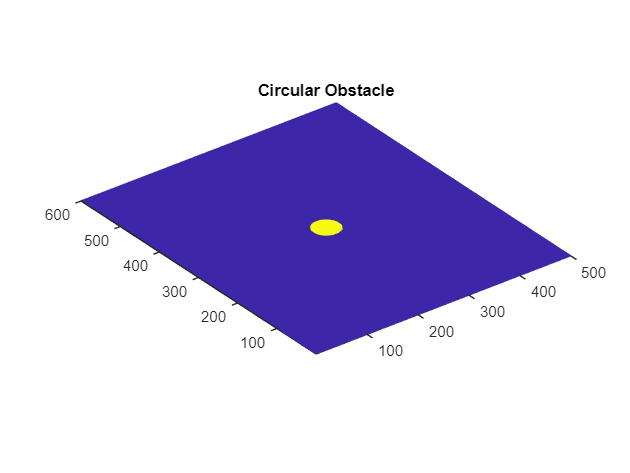

%circular obstacle 

nrows = 600;
ncols = 500;

obstacle = false(nrows,ncols);

[x, y] = meshgrid(1:ncols, 1:nrows);

Xc = ncols/2;
Yc = nrows/2;
R = 25;

t = ((x-Xc).^2+ (y-Yc).^2) < R^2;
obstacle(t) = true;

figure;
m = mesh(obstacle);
axis("equal");
title("Circular Obstacle")